# Mini-projet - Localisation de source audio

### Burtscher Clément - Pêcheux Nicolas

### ROB 5 (Polytech) / M2 ISSI

clear, clc, close all;

### 2. Implémentation de la localisation de l’azimuth d’une source binaurale (avec/sans utilisation des HRTF)

[https://www.canal-u.tv/producteurs/inria/cours_en_ligne/binaural_hearing_for_robots/3_sound_source_localization](https://www.canal-u.tv/producteurs/inria/cours_en_ligne/binaural_hearing_for_robots/3_sound_source_localization)

En traitement du signal, il est courant de faire de l'analyse spectrale, en appliquant la transformée de Fourier (FT) aux signaux des microphones

En principe, on devrait utiliser la transformée de Fourier discrète (DFT) : on utilise la DFT appliquée à une courte période de temps, appelée transformée de Fourier à court terme (STFT)

En appliquant la STFT à un signal à pas de temps discrets, on obtient un spectrogramme, dont chacun des points indique le niveau d'oscillations contenues dans le signal à l'instant t et la fréquence f

En supposant qu'il y une seule source émetteuse, les signaux reçus par chaque oreille sont différents, et peuvent être caractérisés par 2 grandeurs :

- Interaural Time Difference (ITD) ou Time Difference Of Arrival (TDOA) ou Interaural Phase Difference (IPD) : les signaux atteignent à un instant t différent chaque oreille

- Interaural Level (ou Intensity) Difference (ILD) : les signaux ont une intensité différente

A partir de ces 2 grandeurs on peut déterminer la localisation de la source

Soient 2 microphones enregistrant 2 signaux x1(t) et x2(t)

- On applique la STFT aux 2 signaux

-  (Filtrage ou non des 2 signaux)

- On calcule la densité spectrale de puissance (cross-PSD : cross power spectral density) pour chaque fréquence

- ITD/TDOA = phase offset qui maximise le cross-PSD parmi toutes les fréquences

% Séance 2/12

Calculer les indices binauraux ILD et ITD pour chaque angle (elevation = 0) : récupérer la "carte"

Faire la même chose pour les microphones

La STFT permet de calculer un theta pour chaque échantilon de temps : le theta retenu est le plus probable (celui qui apparait le plus de fois --> on peut le voir avec des histogrammes, c'est pas forcément la moyenne !)

#### 2.a. Un 1er modèle simpliste : géométrie épipolaire auditive (AEG)

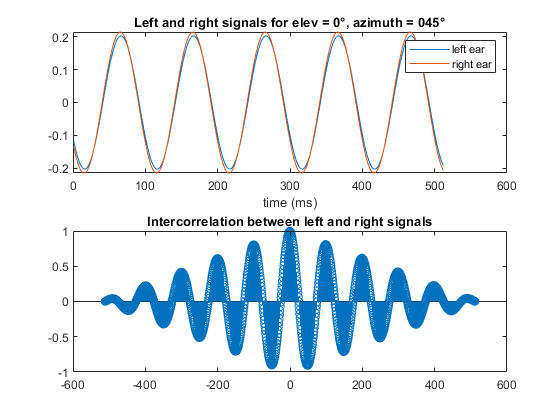

% Load an audio file from KEMAR
angle_l = '045'; % 3 chiffres !
angle_r = '315'; % 3 chiffres !
source1 = '440bis'; % Fréquence de la sinusoïde
source2 = '16k';
f = 440;
% angle = 90° --> source en face du speaker
filename1 = ['KEMAR\full\elev0\L0e',angle_l,'a.wav'];
filename2 = ['KEMAR\full\elev0\R0e',angle_r,'a.wav'];
[x1,fs1] = audioread(filename1);
[x2,fs2] = audioread(filename2);
d = 0.152; % Distance entre les 2 micros
% Pour un Kemar, d = 15.2 cm
% https://www.gras.dk/files/m/a/KEMAR_Manikin_Measurements.pdf
v = 340; % Vitesse du son

% Load an audio file from sine440_angleX.mat
% load('sine440_angle1.mat');
% x1 = x_mic(:,1);
% x2 = x_mic(:,2);
% fs1 = length(x_mic);
% fs2 = length(x_mic);
% d = ANTENNE.D; % Distance entre les 2 micros
% v = ANTENNE.C; % Vitesse du son

% [S1,f1,t1] = compute_stft(x1,fs1);
% [S2,f2,t2] = compute_stft(x2,fs2);
% plot_stft(t1,f1,S1);
% plot_stft(t2,f2,S2);

% Discrete Fourier Transform
% fft1 = fft(x1);
% fft2 = fft(x2);

% HRTF convolution
% HRTF = TF(HRIR)

%[audio,Fs] = audioread('sine440.wav');
[audio,Fs] = audioread(['sine',source1,'.wav']);
%sound(sine440);
%pause(8);
%[S_sine,f_sine,t_sine] = compute_stft(sine440,Fs);
left = conv(x1,audio,'same');
%sound(left);
%pause(8);
right = conv(x2,audio,'same');
%sound(right);
%left = audio;
%right = audio;
%right = [zeros(441,1) ; audio(1:43659,1)];
data = azim(left,right,v,d,Fs,angle_l,f);

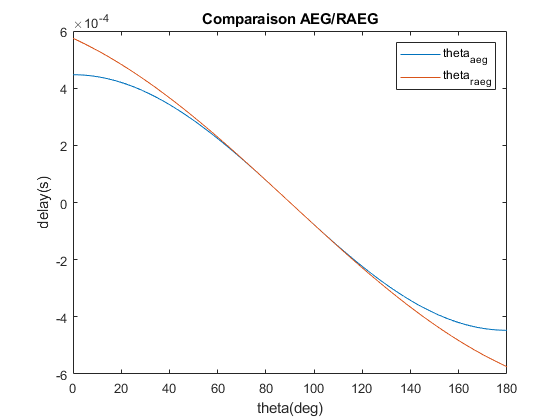

% On doit avoir dist < d


% Calcul du TDOA ou ITD
%theta1 = compute_ITD(x1,x2,v,d,fs1,angle);

plot_RAEG(d,v);

Il faut restreindre l'étude à [0°;180°] car au-delà de 180° la RAEG déconne

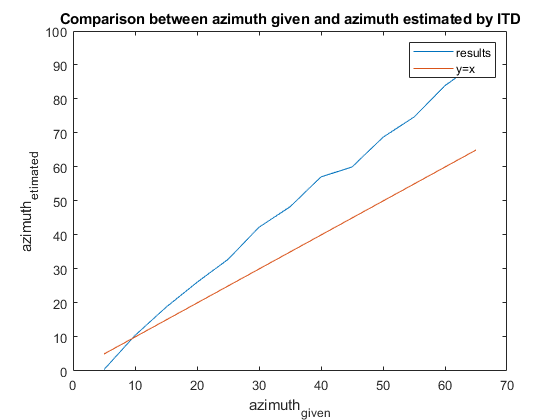

liste_angles_given_l = {'005','010','015','020','025','030','035','040','045','050','055','060','065'};
liste_angles_given_r = {'275','280','285','290','295','300','305','310','315','320','325','330','335'};
liste_angles_given = [5,10,15,20,25,30,35,40,45,50,55,60,65];
kmax = length(liste_angles_given);
offset = 30*ones(1,kmax);

[audio,Fs] = audioread(['sine',source1,'.wav']);
comparison_itd(liste_angles_given_l,liste_angles_given_r,liste_angles_given,kmax,audio,v,d,Fs,offset);

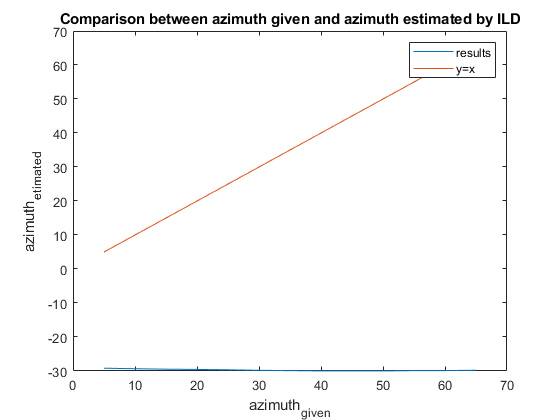


[audio,Fs] = audioread(['sine',source2,'.wav']);
f = 16000;
comparison_ild(liste_angles_given_l,liste_angles_given_r,liste_angles_given,kmax,audio,f,offset);

#### 2.b. Un 2nd modèle plus développé : géométrie épipolaire auditive révisée (RAEG)

#### 2.c. Un 3ème modèle acoustique : Scattering Theory